# Bode's stability criterion: Tutorial

#### Arun K. Tangirala

*April 19, 2020*

In this tutorial, we shall illustrate the Bode's stability criterion for LTI systems. We shall also take this opportunity to introduce the concepts of stability margins.

**Example 1: First-order in feedback with a P-controller**

The system of interest is $G_p \left(s\right)=\frac{K_p }{\tau_p s+1}$ in feedback with a proportional controller $G_c \left(s\right)=K_c$. The loop transfer function is given by $L_G \left(s\right)=G_p G_c \ldotp$ We know that the system is stable $\forall \;K_c K_p >-1\ldotp$ Thus, the system should not have any phase crossover frequency.

% Process
Kp = 2;
taup = 10;
Gp = tf(Kp,[taup 1]);

% Controller
Kc = 3

Kc = 3

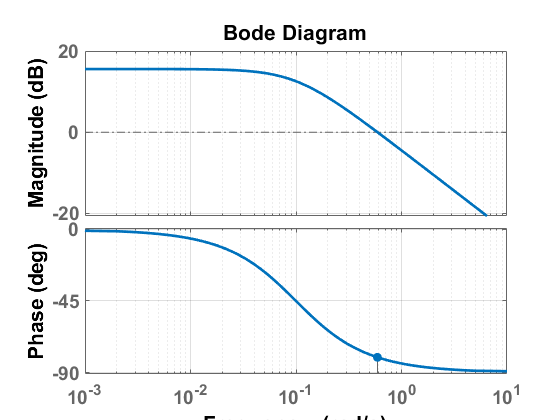

Gc = tf(Kc);

% Loop transfer function
Lg1 = series(Gc,Gp);

% Bode plot of Lg
hbp = bodeplot(Lg1);
hbp.showCharacteristic('AllStabilityMargins')
hstr_bp = getoptions(hbp);
hstr_bp.Title.FontSize = 16;
hstr_bp.XLabel.FontSize = 16;
hstr_bp.XLabel.FontWeight = 'bold';
hstr_bp.YLabel.FontSize = 16;
hstr_bp.YLabel.FontWeight = 'bold';
hstr_bp.TickLabel.FontSize = 14;
hstr_bp.TickLabel.FontWeight = 'bold';
setoptions(hbp,hstr_bp)

ax_bp = findobj(gcf,'type','axes');
ax_line = findobj(ax_bp,'type','line');
set(ax_line,'Linewidth',2,'Markersize',8)


% figure
% hmg = margin(Lg1);

**Example 2; Second-order system in feedback with a P controller**

Now consider a second-order system $G_p \left(s\right)=\frac{K_p }{\left(\tau_1 s+1\right)\left(\tau_2 s+1\right)}$ in feedback with a proportional controller $G_c \left(s\right)=K_c$. The closed-loop system is stable, as we know $\forall \;K_c K_p >-1$. Therefore, evenf or this system, we should not expect to see a phase crossover frequency. However, as before the gain crossover frequency will exist.

% Process
Kp = 2;
taup1 = 14;
taup2 = 10;
Gp2 = tf(Kp,[taup1*taup2 (taup1+taup2) 1]);

% Controller
Kc = 3

Kc = 3

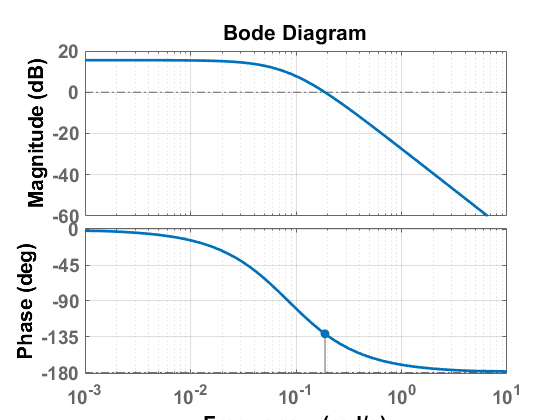

Gc = tf(Kc);

% Loop transfer function
Lg2 = series(Gc,Gp2);

% Bode plot of Lg
hbp = bodeplot(Lg2);
hbp.showCharacteristic('AllStabilityMargins')
hstr_bp = getoptions(hbp);
hstr_bp.Title.FontSize = 16;
hstr_bp.XLabel.FontSize = 16;
hstr_bp.XLabel.FontWeight = 'bold';
hstr_bp.YLabel.FontSize = 16;
hstr_bp.YLabel.FontWeight = 'bold';
hstr_bp.TickLabel.FontSize = 14;
hstr_bp.TickLabel.FontWeight = 'bold';
setoptions(hbp,hstr_bp)

ax_bp = findobj(gcf,'type','axes');
ax_line = findobj(ax_bp,'type','line');
set(ax_line,'Linewidth',2,'Markersize',8)


% figure
% hmg = margin(Lg1);


The root locus plot is obtained below

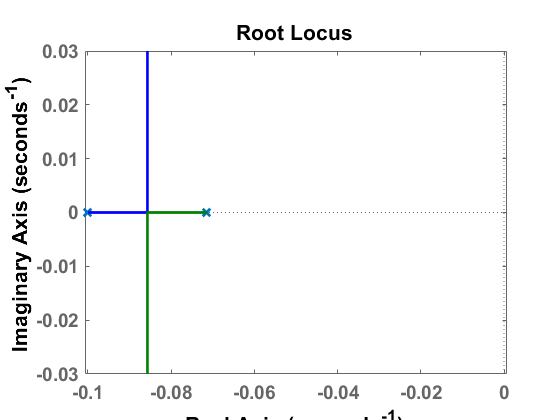

% Effective OL system
Ls = Gp2;
hrl = rlocusplot(Ls);
hstr_rl = getoptions(hrl);
hstr_rl.Title.FontSize = 16;
hstr_rl.XLabel.FontSize = 16;
hstr_rl.XLabel.FontWeight = 'bold';
hstr_rl.YLabel.FontSize = 16;
hstr_rl.YLabel.FontWeight = 'bold';
hstr_rl.TickLabel.FontSize = 14;
hstr_rl.TickLabel.FontWeight = 'bold';
setoptions(hrl,hstr_rl)
grid off

a_rl = findobj(gca,'type','line');
set(a_rl,'Linewidth',2,'Markersize',8)

**Example 3: Second-order system in feedback with a PI controller**

Consider the same second-order system $G_p \left(s\right)=\frac{K_p }{\left(\tau_1 s+1\right)\left(\tau_2 s+1\right)}$ in feedback with a PI controller $G_c \left(s\right)=K_c +\frac{K_i }{s}$. The closed-loop system is not necessarily stable for all values of $K_c$ and $K_I$. Bode plot reflects this fact as shown below.

% Process
Kp = 2;
taup1 = 14;
taup2 = 10;
Gp2 = tf(Kp,[taup1*taup2 (taup1+taup2) 1]);

% Controller
Kc = 3

Kc = 3

KI = 0.9

KI = 0.9000

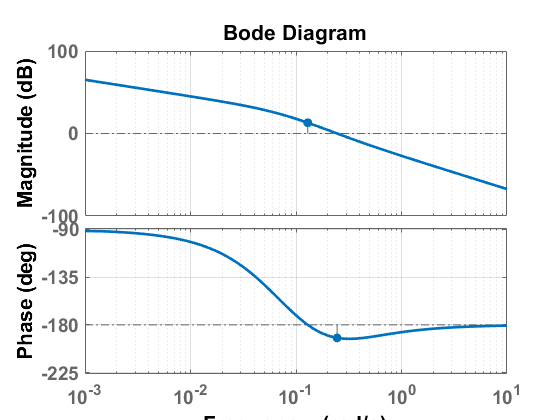

Gc2 = tf([Kc KI],[1 0]);

% Loop transfer function
Lg3 = series(Gc2,Gp2);

% Bode plot of Lg
figure
hbp = bodeplot(Lg3);
hbp.showCharacteristic('AllStabilityMargins')
hstr_bp = getoptions(hbp);
hstr_bp.Title.FontSize = 16;
hstr_bp.XLabel.FontSize = 16;
hstr_bp.XLabel.FontWeight = 'bold';
hstr_bp.YLabel.FontSize = 16;
hstr_bp.YLabel.FontWeight = 'bold';
hstr_bp.TickLabel.FontSize = 14;
hstr_bp.TickLabel.FontWeight = 'bold';
setoptions(hbp,hstr_bp)

ax_bp = findobj(gcf,'type','axes');
ax_line = findobj(ax_bp,'type','line');
set(ax_line,'Linewidth',2,'Markersize',8)


% figure
% hmg = margin(Lg1);

We can compare the result with RL method by treating $K_I \;$as the design parameter. The effective open-loop transfer function is given by


$$L\left(s\right)=\frac{K_p }{\tau_1 \tau_2 s^3 +\left(\tau_1 +\tau_2 \right)s^2 +s\left(1+K_c K_p \right)}$$


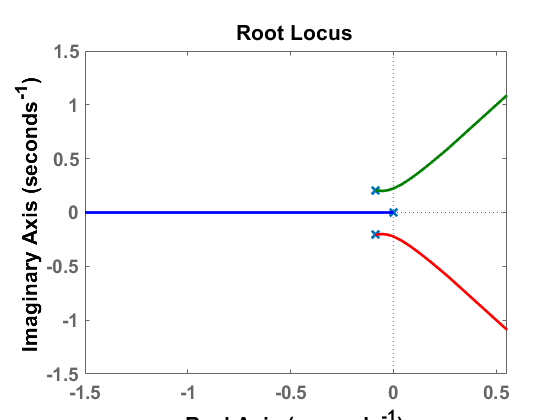

% Process
s = tf('s');
num_Gp2 = Kp; 
den_Gp2 = taup1*taup2*s^2 + (taup1 + taup2)*s + 1;
Gp2 = num_Gp2 / den_Gp2;
%KI = 0.1;
Kc = 3;

% Effective OL system
%Ls = s*num_Gp2/(s*den_Gp2 + KI*num_Gp2);
Ls = num_Gp2/(s*(den_Gp2 + Kc*Kp));
hrl = rlocusplot(Ls);
hstr_rl = getoptions(hrl);
hstr_rl.Title.FontSize = 16;
hstr_rl.XLabel.FontSize = 16;
hstr_rl.XLabel.FontWeight = 'bold';
hstr_rl.YLabel.FontSize = 16;
hstr_rl.YLabel.FontWeight = 'bold';
hstr_rl.TickLabel.FontSize = 14;
hstr_rl.TickLabel.FontWeight = 'bold';
setoptions(hrl,hstr_rl)
grid off

a_rl = findobj(gca,'type','line');
set(a_rl,'Linewidth',2,'Markersize',8)

The crossover frequency identified from the RL plot can also be determined from the Bode plot of the effective loop transfer function $L\left(s\right)$.

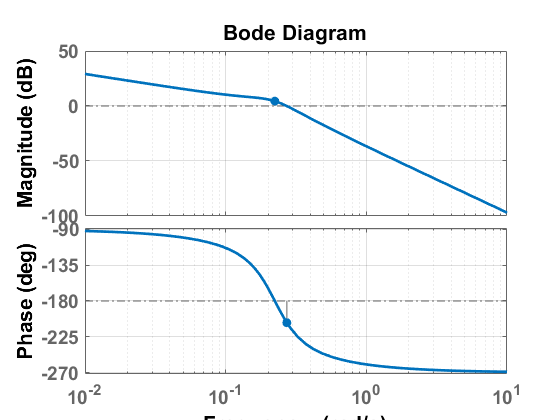

figure
hbp = bodeplot(Ls);
hbp.showCharacteristic('AllStabilityMargins')
hstr_bp = getoptions(hbp);
hstr_bp.Title.FontSize = 16;
hstr_bp.XLabel.FontSize = 16;
hstr_bp.XLabel.FontWeight = 'bold';
hstr_bp.YLabel.FontSize = 16;
hstr_bp.YLabel.FontWeight = 'bold';
hstr_bp.TickLabel.FontSize = 14;
hstr_bp.TickLabel.FontWeight = 'bold';
setoptions(hbp,hstr_bp)

ax_bp = findobj(gcf,'type','axes');
ax_line = findobj(ax_bp,'type','line');
set(ax_line,'Linewidth',2,'Markersize',8)


[~,~,ph_wc,gain_wg] = margin(Ls);

The phase crossover frequency of $L\left(s\right)$is found to be 

fprintf('%4.4f rad/sec \n',ph_wc)

0.2236 rad/sec 


which agrees with the value determined from root locus.

**Example 4: FOPTD system in feedback with a P-controller**

Consider next an FOPTD system $G_p \left(s\right)=\frac{K_p }{\tau_p s+1}e^{-\textrm{Ds}}$ in feedback with a P-controller $G_c \left(s\right)=K_c$, where $K_p =2,\tau_p =10,D=2$ and $K_c =3$. Is the feedback system stable?

%% Example 4

% Process
Kp = 2;
taup = 10;
D = 1;

Gp4 = tf(Kp,[taup 1]);
Gp4.iodelay = D;

% Controller
Kc = 3

Kc = 3

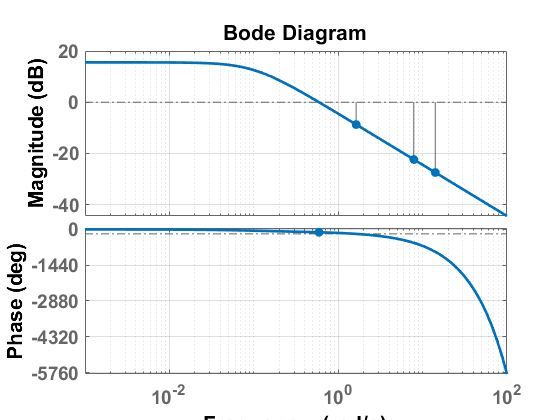

Gc = tf(Kc);

% Loop gain
Lg4 = series(Gc,Gp4);

figure
hbp = bodeplot(Lg4);
hbp.showCharacteristic('AllStabilityMargins')
hstr_bp = getoptions(hbp);
hstr_bp.Title.FontSize = 16;
hstr_bp.XLabel.FontSize = 16;
hstr_bp.XLabel.FontWeight = 'bold';
hstr_bp.YLabel.FontSize = 16;
hstr_bp.YLabel.FontWeight = 'bold';
hstr_bp.TickLabel.FontSize = 14;
hstr_bp.TickLabel.FontWeight = 'bold';
setoptions(hbp,hstr_bp)

ax_bp = findobj(gcf,'type','axes');
ax_line = findobj(ax_bp,'type','line');
set(ax_line,'Linewidth',2,'Markersize',8)

We can determine the maximum possible gain for $K_c$ by setting $s=j\omega \;$in the CE equation and solving for $\omega \;$and $K_{\textrm{cu}}$. The solutions to the resulting non-linear equations are indeed the ones given out by the Bode plot of $L\left(s\right)$.

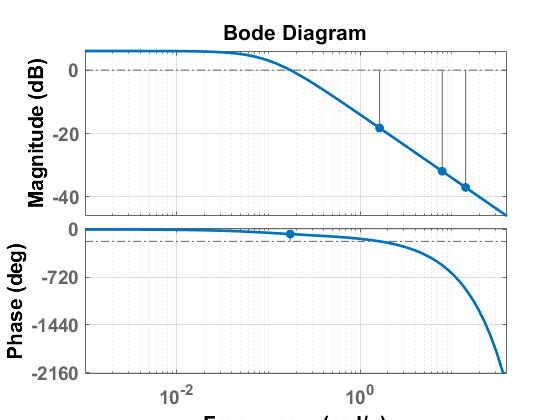

%% Example 4 with Kc = 1

% Process
Kp = 2;
taup = 10;
D = 1;

Gp4 = tf(Kp,[taup 1]);
Gp4.iodelay = D;

% Controller
Kc = 1; Gc = tf(Kc);

% Loop gain
Lgs = series(Gc,Gp4);

figure
hbp = bodeplot(Lgs);
hbp.showCharacteristic('AllStabilityMargins')
hstr_bp = getoptions(hbp);
hstr_bp.Title.FontSize = 16;
hstr_bp.XLabel.FontSize = 16;
hstr_bp.XLabel.FontWeight = 'bold';
hstr_bp.YLabel.FontSize = 16;
hstr_bp.YLabel.FontWeight = 'bold';
hstr_bp.TickLabel.FontSize = 14;
hstr_bp.TickLabel.FontWeight = 'bold';
hstr_bp.Xlim = {[1e-003 40]};
setoptions(hbp,hstr_bp)

ax_bp = findobj(gcf,'type','axes');
ax_line = findobj(ax_bp,'type','line');
set(ax_line,'Linewidth',2,'Markersize',8)


[Gm,~,ph_co,gain_co] = margin(Lgs)

Gm = 8.1746

ph_co = 1.6319

gain_co = 0.1732

Kcmax = 10^(8.1746/20)

Kcmax = 2.5629

Next, consider a process with multiple crossover frequencies in feedback with a P-controller. The system has a special feature in that it has more than one phase crossover frequency, as will be seen shortly.

**Example 5: Process with multiple crossover frequencies in feedback with a P-controller**

Consider the process $G_p \left(s\right)=\frac{\left(s+1\right)\left(0\ldotp 1s+1\right)}{s^3 \left(0\ldotp 01s+1\right)\left(0\ldotp 002s+1\right)}$ in feedback with a proportional controller $G_c \left(s\right)=K_c$. Choose $K_c =2100$ (a high controller gain). The Bode plot for the loop-open system $L_G \left(s\right)=G_c \left(s\right)G_p \left(s\right)\;$is shown below.

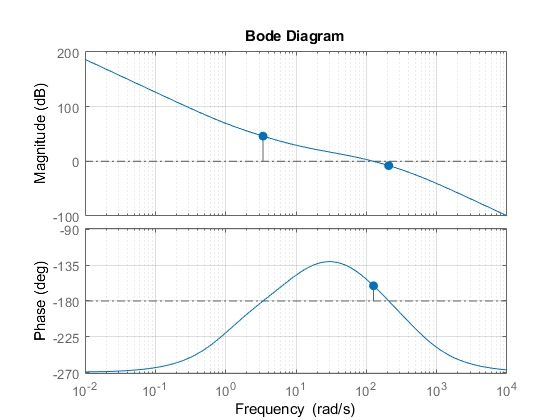

%% Example 5 with Kc = 2100

% Process
Kp = 1;
tau1 = 0.01; tau2 = 0.002;
taun1 = 1; taun2 = 0.1;

s = tf('s');
num_Gp5 = Kp*(taun1*s + 1)*(taun2*s + 1);
den_Gp5 = s^3*(tau1*s + 1)*(tau2*s + 1);
Gp_5 = num_Gp5/den_Gp5;

% Controller
Kc = 2100; Gc = tf(Kc);

% Loop gain
Lg5 = series(Gc,Gp_5);

figure
hbp = bodeplot(Lg5);
hbp.showCharacteristic('AllStabilityMargins')

% hstr_bp = getoptions(hbp);
% hstr_bp.Title.FontSize = 16;
% hstr_bp.XLabel.FontSize = 16;
% hstr_bp.XLabel.FontWeight = 'bold';
% hstr_bp.YLabel.FontSize = 16;
% hstr_bp.YLabel.FontWeight = 'bold';
% hstr_bp.TickLabel.FontSize = 14;
% hstr_bp.TickLabel.FontWeight = 'bold';
% %hstr_bp.Xlim = {[1e-003 40]};
% setoptions(hbp,hstr_bp)
% 
% ax_bp = findobj(gcf,'type','axes');
% ax_line = findobj(ax_bp,'type','line');
% set(ax_line,'Linewidth',2,'Markersize',8)

We observe two phase crossover frequencies for the loop-open transfer function, one at 3.37 rad/sec and the other at 296.4765 rad/sec with gain margins of -46.2 dB and 13.3 dB, respectively. 

The magnitude of $L_G \left(j\omega \right)$ is greater than unity at the first crossover frequency, while it is less than unity at the second frequency. However, unlike in the previous cases, the closed-loop system is stable despite the fact that $\left|L_G \left(j\omega_{\textrm{c1}} \right)\right|>1$ (att the first crossover frequency). The reason is that the first crossover frequency does not correspond to the crossover point on the locus (leave it to the student to verify this statement). 

To understand the above point recall that the purpose of turning to the FRF is to identify crossover points on the IA for the locus. Since any point on the locus has to satisfy the angle criterion, we search for frequency / frequencies such that $\angle L\left(j\omega \right)=-{180}^{\circ }$. For the systems that we have studied until now, this approach gave us only one solution which was indeed a point on the locus (or if no solution, then the locus did not crossover into the RHP). However, this example shows that the FRF based approach to determining the crossover point can yield multiple solutions and not all of them are true solutions - there can be spurious ones! In this case, the second crossover frequency corresponds to a true solution, i.e., on the imaginary axis. This is one of the limitations that we are likely to face with Bode's approach to stability analysis.

We next take up a second-order-plus-time-delay system in feedback with a PI controller parametrized by $K_c$ and $\tau_I$. We shall also use this example to illustrate the notions of gain and phase margin.

**Example 6: SOPTD system in feedback with a PI controller**

Consider a second-order system $G_p \left(s\right)=\frac{2}{\left(14s+1\right)\left(7s+1\right)}e^{-2s}$ placed in feedback with a PI controller $G_c \left(s\right)=K_c \left(1+\frac{1}{\tau_I s}\right)$, where $K_c =2$, $\tau_I =10$.

%% Example 6

% Process
Kp = 2; tau1 = 10; tau2 = 14; D = 2;

Gp6 = tf(Kp,[tau1*tau2 (tau1 + tau2) 1]);
Gp6.iodelay = 2;

% Controller
Kc = 1
tauI =  10
Gc_pi = Kc*tf([tauI 1],[tauI 0]);

% Loop transfer function
Lg6 = series(Gc_pi,Gp6);

figure
hbp = bodeplot(Lg6);
hbp.showCharacteristic('AllStabilityMargins')
hstr_bp = getoptions(hbp);
hstr_bp.Title.FontSize = 16;
hstr_bp.XLabel.FontSize = 16;
hstr_bp.XLabel.FontWeight = 'bold';
hstr_bp.YLabel.FontSize = 16;
hstr_bp.YLabel.FontWeight = 'bold';
hstr_bp.TickLabel.FontSize = 14;
hstr_bp.TickLabel.FontWeight = 'bold';
%hstr_bp.Xlim = {[1e-003 40]};
setoptions(hbp,hstr_bp)

ax_bp = findobj(gcf,'type','axes');
ax_line = findobj(ax_bp,'type','line');
set(ax_line,'Linewidth',2,'Markersize',8)

The penultimate example is that of a third-order system placed in feedback with a P-controller. The purpose of this example is to primarily illustrate the concepts of gain and phase margin.

**Example 7: Third-order system in feedback with a P-controller**

Consider a third-order system $G_p \left(s\right)=\frac{2}{\left(10s+1\right)\left(4s+1\right)\left(2s+1\right)}$ placed in feedback with a proportional controller $G_c \left(s\right)=K_c$, with $K_c =2$.

The Bode plot is obtained using the script below.

%% Example 7

% Process
Kp = 2; tau1 = 10; tau2 = 4; tau3 = 2;

s = tf('s');
Gp7 = Kp/((tau1*s+1)*(tau2*s + 1)*(tau3*s + 1));

% Controller
Kc = 2
Gc_p = tf(Kp);

% Loop transfer function
Lg7 = series(Gc_p,Gp7);

figure
hbp = bodeplot(Lg7);
hbp.showCharacteristic('AllStabilityMargins')
hstr_bp = getoptions(hbp);
hstr_bp.Title.FontSize = 16;
hstr_bp.XLabel.FontSize = 16;
hstr_bp.XLabel.FontWeight = 'bold';
hstr_bp.YLabel.FontSize = 16;
hstr_bp.YLabel.FontWeight = 'bold';
hstr_bp.TickLabel.FontSize = 14;
hstr_bp.TickLabel.FontWeight = 'bold';
%hstr_bp.Xlim = {[1e-003 40]};
setoptions(hbp,hstr_bp)

ax_bp = findobj(gcf,'type','axes');
ax_line = findobj(ax_bp,'type','line');
set(ax_line,'Linewidth',2,'Markersize',8)

Using this example, we illustrate the importance of PM in determining how much error in delay can be tolerated by the control system before it destabilizes (uncertainty in gains, their calculations using GM and its illustration are left to the reader). We can compute the gain and phase margins for this system as below

[Gm,Pm,Wc,Wg] = margin(Lg7)

For illustration purposes, we consider two delays, $D_1 =0\ldotp 7\times \textrm{DM}$and $D_2 =1\ldotp 2\times \textrm{DM}$, where $\textrm{DM}$is the delay margin calculated as 

$\textrm{DM}=\frac{\textrm{PM}}{\omega_g }=43\ldotp 1\times \frac{\pi }{180}\times \frac{1}{0\ldotp 24}=3\ldotp 136$ seconds

del_margin = Pm*(pi/180)*(1/0.24)

Step responses of the two closed-loop systems resulting from systems with these two delays can be now compared.

% System with D1 delay
D1 = 0.7*del_margin;
D2 = 1.2*del_margin;

Gp7_1 = Gp7; Gp7_2 = Gp7;
Gp7_1.iodelay = D1;
Gp7_2.iodelay = D2;

Gcl1 = feedback(series(Gp7_1,Gc_p),1)
Gcl2 = feedback(series(Gp7_2,Gc_p),1)

% Step response
figure
subplot(211)
hsres1 = stepplot(Gcl1);
hstr_sr = getoptions(hsres1);
hstr_sr.Title.FontSize = 14;
hstr_sr.Title.String = 'Step response of G_{CL} with Process Delay = 0.7 \times DM';
hstr_sr.XLabel.String = '';
hstr_sr.XLabel.FontSize = 16;
hstr_sr.XLabel.FontWeight = 'bold';
hstr_sr.YLabel.FontSize = 16;
hstr_sr.YLabel.FontWeight = 'bold';
hstr_sr.TickLabel.FontSize = 14;
hstr_sr.TickLabel.FontWeight = 'bold';
%hstr_bp.Xlim = {[1e-003 40]};
setoptions(hsres1,hstr_sr)

%ax_sr = findobj(gcf,'type','axes');
%ax_line = findobj(ax_sr,'type','line');
%set(ax_line,'Linewidth',2,'Markersize',8)

subplot(212)
hsres2 = stepplot(Gcl2);
hstr_sr = getoptions(hsres2);
hstr_sr.Title.FontSize = 14;
hstr_sr.Title.String = 'Step response of G_{CL} with Process Delay = 1.2 \times DM';
hstr_sr.XLabel.FontSize = 16;
hstr_sr.XLabel.FontWeight = 'bold';
hstr_sr.YLabel.FontSize = 16;
hstr_sr.YLabel.FontWeight = 'bold';
hstr_sr.TickLabel.FontSize = 14;
hstr_sr.TickLabel.FontWeight = 'bold';
%hstr_bp.Xlim = {[1e-003 40]};
setoptions(hsres2,hstr_sr)

ax_sr = findobj(gcf,'type','axes');
ax_line = findobj(ax_sr,'type','line');
set(ax_line,'Linewidth',2,'Markersize',8)

**Example 8: System with multiple IA roots in feedback with a P controller**

Consider the following system


$$G_p \left(s\right)=\frac{2\left(2s+1\right)}{s^2 \left(s+1\right)\left(0\ldotp 5s+1\right)}$$


in feedback with a P controller $G_c \left(s\right)=K_c$, where $K_c =60$. Study the stability characteristics of the CL system using BSC.

%% Example 8

% Process
s = tf('s');
num_Gp8 = s^2 + 2*s + 4;
den_Gp8 = s*(s + 4)*(s + 6)*(s^2 + 1.4*s + 1);
Gp8 = num_Gp8/den_Gp8;

% Controller
Kc = 70
Gc = tf(Kc);

% Loop transfer function
Lg8 = series(Gp8,Gc);

figure
hbp = bodeplot(Lg8);
hbp.showCharacteristic('AllStabilityMargins')
hstr_bp = getoptions(hbp);
hstr_bp.Title.FontSize = 16;
hstr_bp.XLabel.FontSize = 16;
hstr_bp.XLabel.FontWeight = 'bold';
hstr_bp.YLabel.FontSize = 16;
hstr_bp.YLabel.FontWeight = 'bold';
hstr_bp.TickLabel.FontSize = 14;
hstr_bp.TickLabel.FontWeight = 'bold';
%hstr_bp.Xlim = {[1e-003 40]};
setoptions(hbp,hstr_bp)

ax_bp = findobj(gcf,'type','axes');
ax_line = findobj(ax_bp,'type','line');
set(ax_line,'Linewidth',2,'Markersize',8)

The root locus for this plot shows the presence of multiple crossings on the IA.

Ls = Gp8;
figure
hrl = rlocusplot(Ls);
hstr_rl = getoptions(hrl);
hstr_rl.Title.FontSize = 16;
hstr_rl.XLabel.FontSize = 16;
hstr_rl.XLabel.FontWeight = 'bold';
hstr_rl.YLabel.FontSize = 16;
hstr_rl.YLabel.FontWeight = 'bold';
hstr_rl.TickLabel.FontSize = 14;
hstr_rl.TickLabel.FontWeight = 'bold';
setoptions(hrl,hstr_rl)
grid off

a_rl = findobj(gca,'type','line');
set(a_rl,'Linewidth',2,'Markersize',8)